**1. Generate the Signal**

- Define parameters for the signal.

- Generate the signal X(t)=sin (ω1t)+2cos (ω2t)+N(t)X(t) = \sin(\omega_1 t) + 2 \cos(\omega_2 t) + N(t)X(t)=sin(ω1�t)+2cos(ω2�t)+N(t).

- Plot the periodogram with different windows and compare the results.

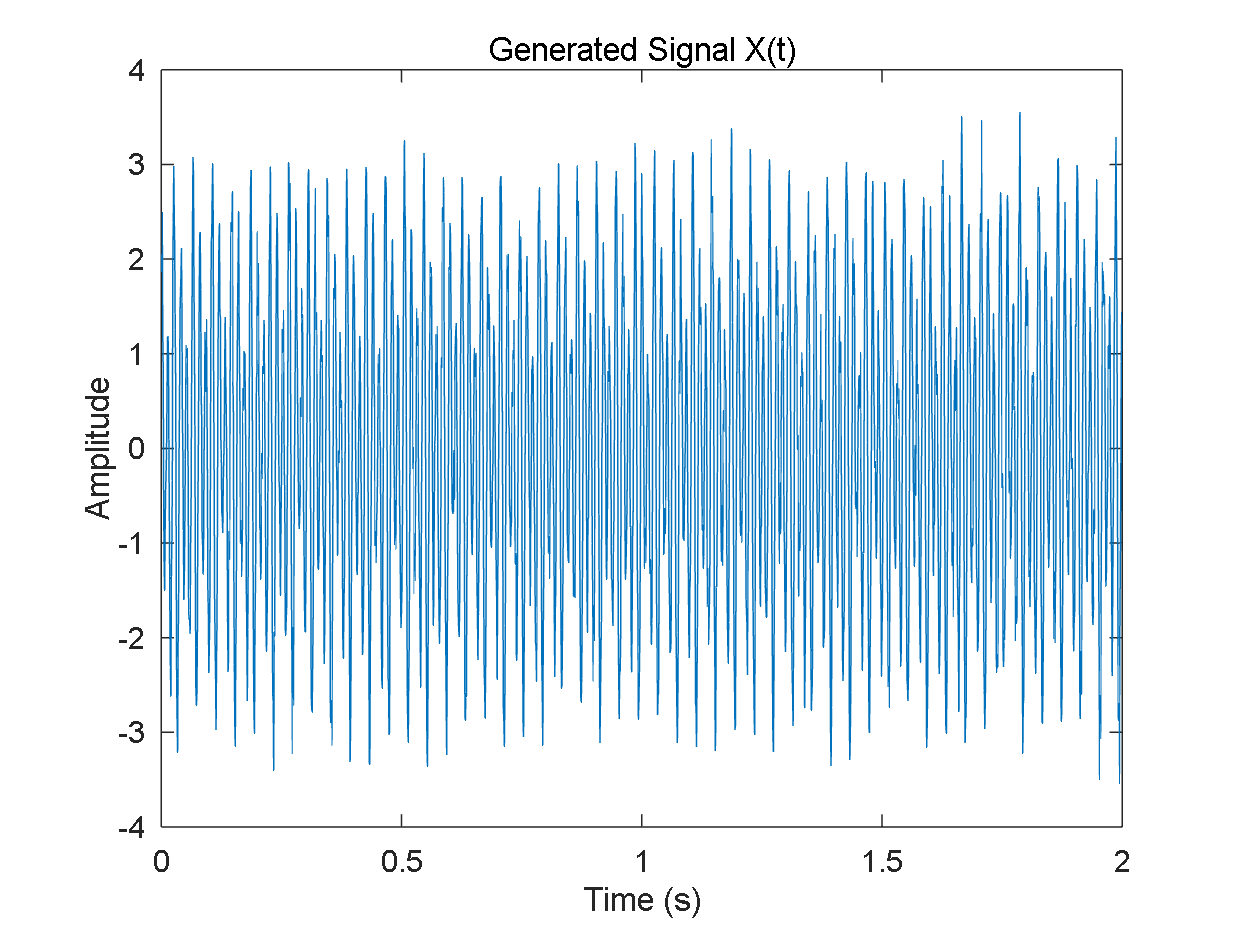

% Define parameters
fs = 1000; % Sample rate in Hz
t = 0:1/fs:2-1/fs; % Time vector for 2 seconds
omega1 = 100 * pi; % Angular frequency in rad/s
omega2 = 150 * pi; % Angular frequency in rad/s
sigma2 = 0.1; % Variance of the Gaussian noise

% Generate the signal
N = sqrt(sigma2) * randn(size(t)); % White Gaussian noise with variance sigma^2
X = sin(omega1 * t) + 2 * cos(omega2 * t) + N;

% Plotting the signal
figure;
plot(t, X);
title('Generated Signal X(t)');
xlabel('Time (s)');
ylabel('Amplitude');

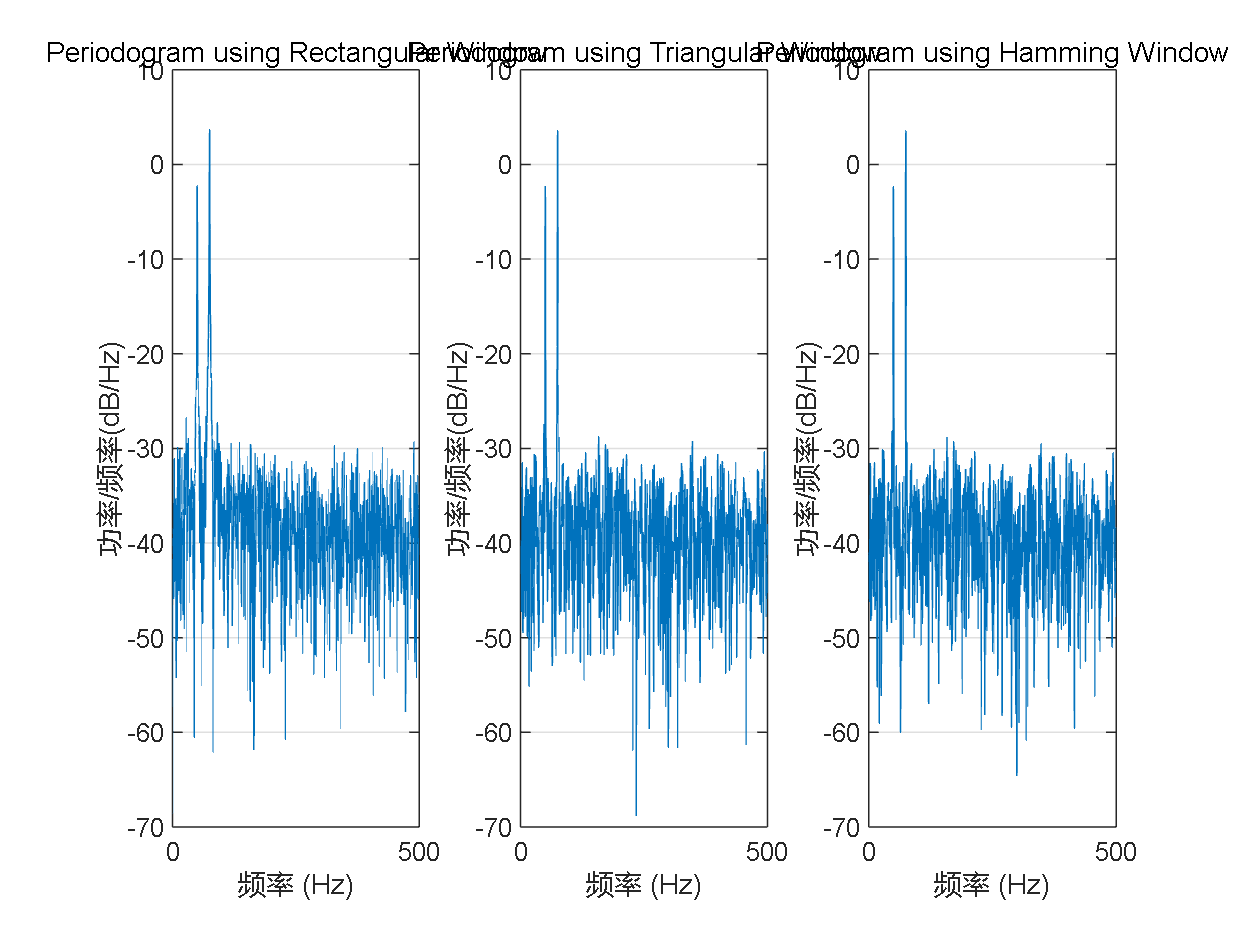


% Compute and plot the periodogram with different windows
figure;
subplot(1, 3, 1);
periodogram(X, rectwin(length(X)), [], fs);
title('Periodogram using Rectangular Window');

subplot(1, 3, 2);
periodogram(X, triang(length(X)), [], fs);
title('Periodogram using Triangular Window');

subplot(1, 3, 3);
periodogram(X, hamming(length(X)), [], fs);
title('Periodogram using Hamming Window');

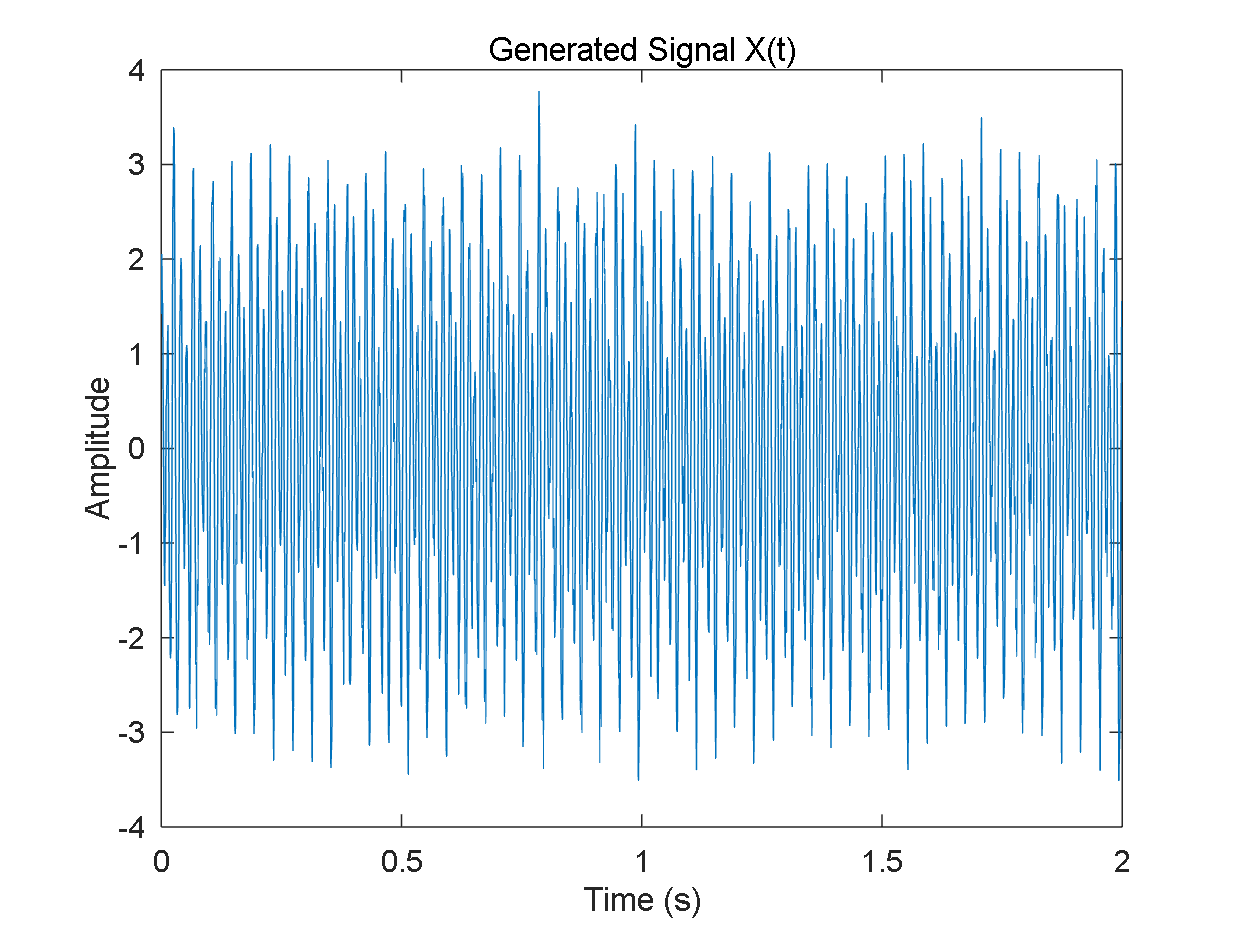

% Define parameters
fs = 1000; % Sample rate in Hz
t = 0:1/fs:2-1/fs; % Time vector for 2 seconds
omega1 = 100 * pi; % Angular frequency in rad/s
omega2 = 150 * pi; % Angular frequency in rad/s
sigma2 = 0.1; % Variance of the Gaussian noise

% Generate the signal
N = sqrt(sigma2) * randn(size(t)); % White Gaussian noise with variance sigma^2
X = sin(omega1 * t) + 2 * cos(omega2 * t) + N;

% Plotting the signal
figure;
plot(t, X);
title('Generated Signal X(t)');
xlabel('Time (s)');
ylabel('Amplitude');

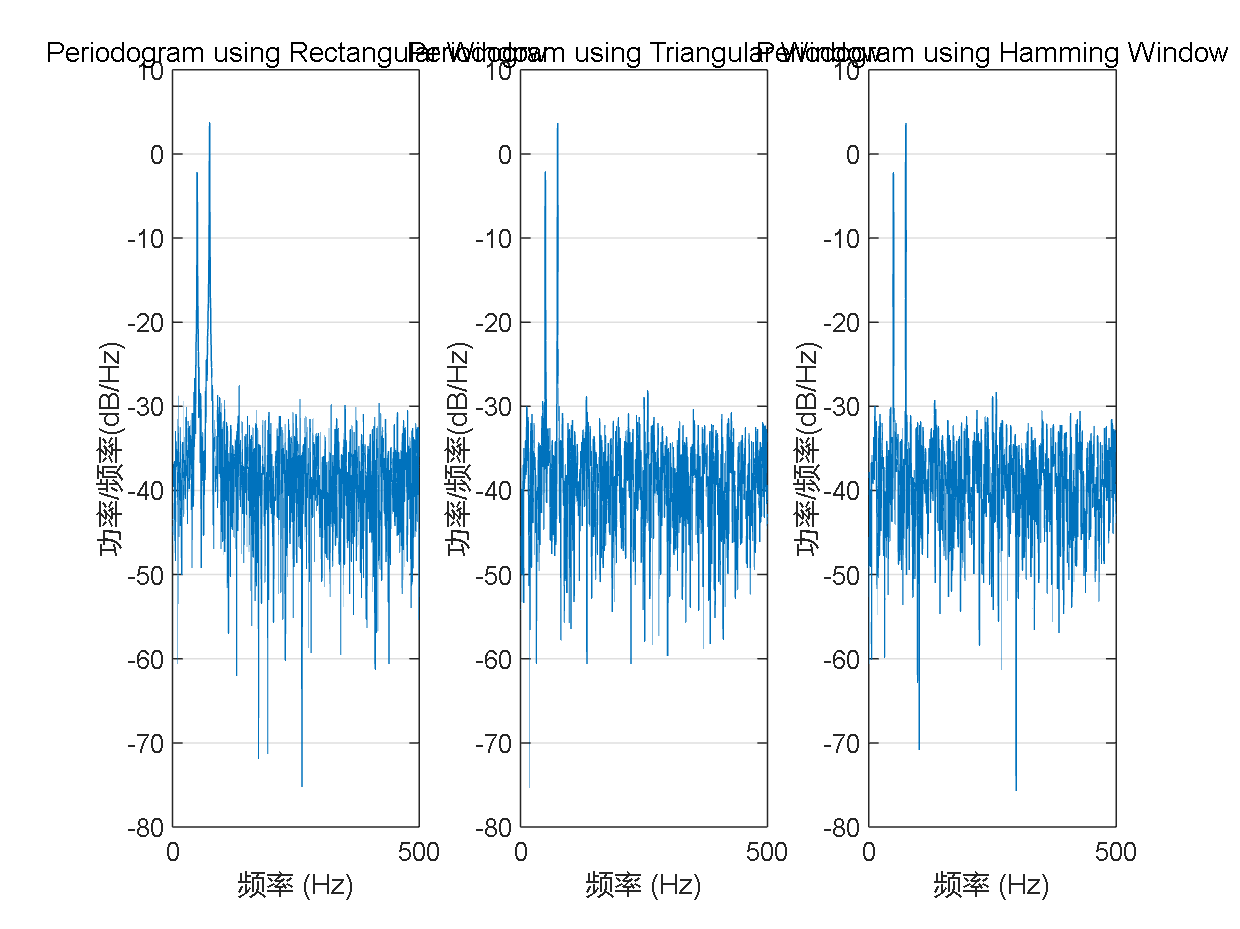


% Compute and plot the periodogram with different windows
figure;
subplot(1, 3, 1);
periodogram(X, rectwin(length(X)), [], fs);
title('Periodogram using Rectangular Window');

subplot(1, 3, 2);
periodogram(X, triang(length(X)), [], fs);
title('Periodogram using Triangular Window');

subplot(1, 3, 3);
periodogram(X, hamming(length(X)), [], fs);
title('Periodogram using Hamming Window');

(a) Effect of Sampling Rate

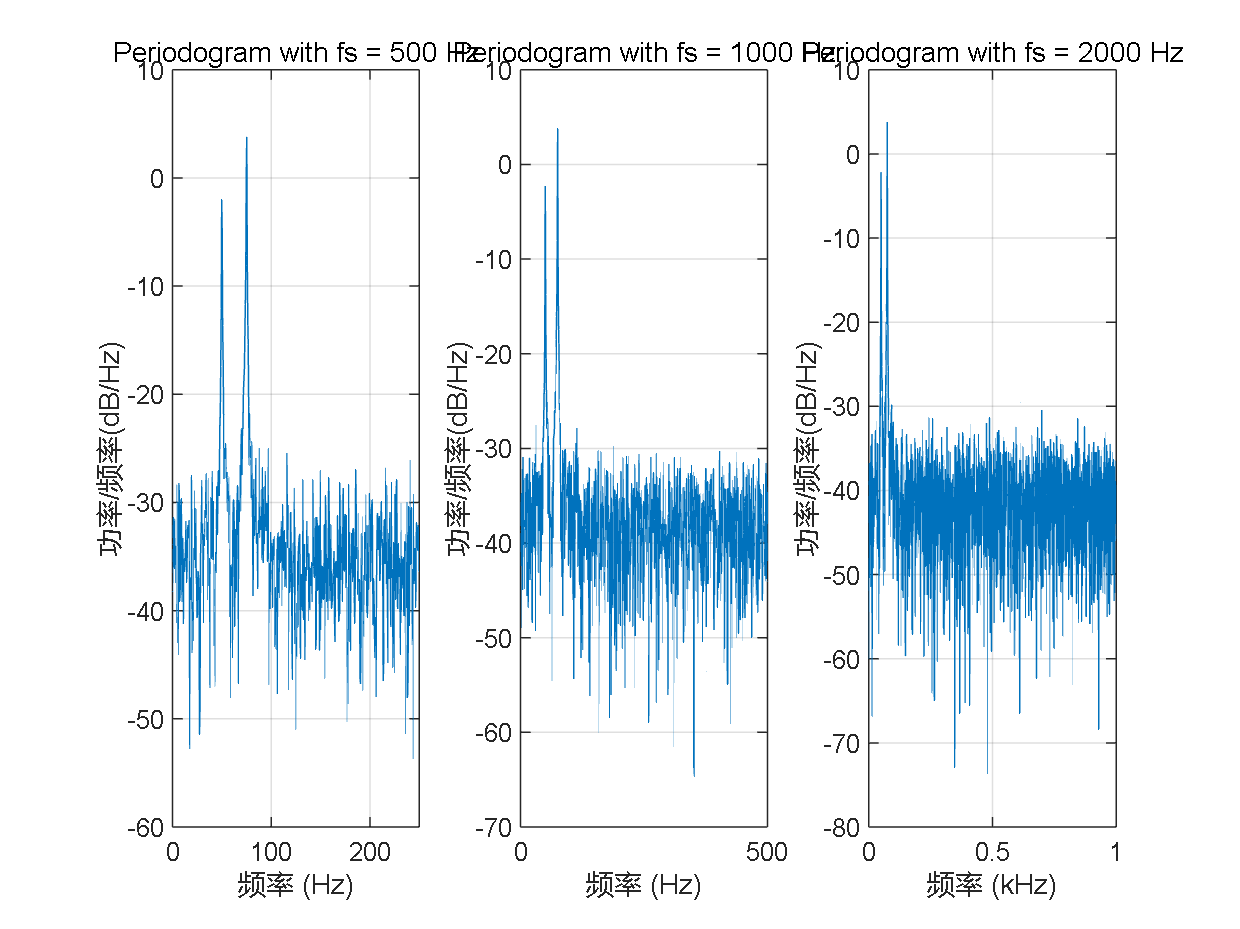

fs_values = [500, 1000, 2000]; % Different sampling rates

figure;
for i = 1:length(fs_values)
    fs = fs_values(i);
    t = 0:1/fs:2-1/fs;
    N = sqrt(sigma2) * randn(size(t));
    X = sin(omega1 * t) + 2 * cos(omega2 * t) + N;
    
    subplot(1, length(fs_values), i);
    periodogram(X, rectwin(length(X)), [], fs);
    title(['Periodogram with fs = ', num2str(fs), ' Hz']);
end

(b) Effect of Signal Length

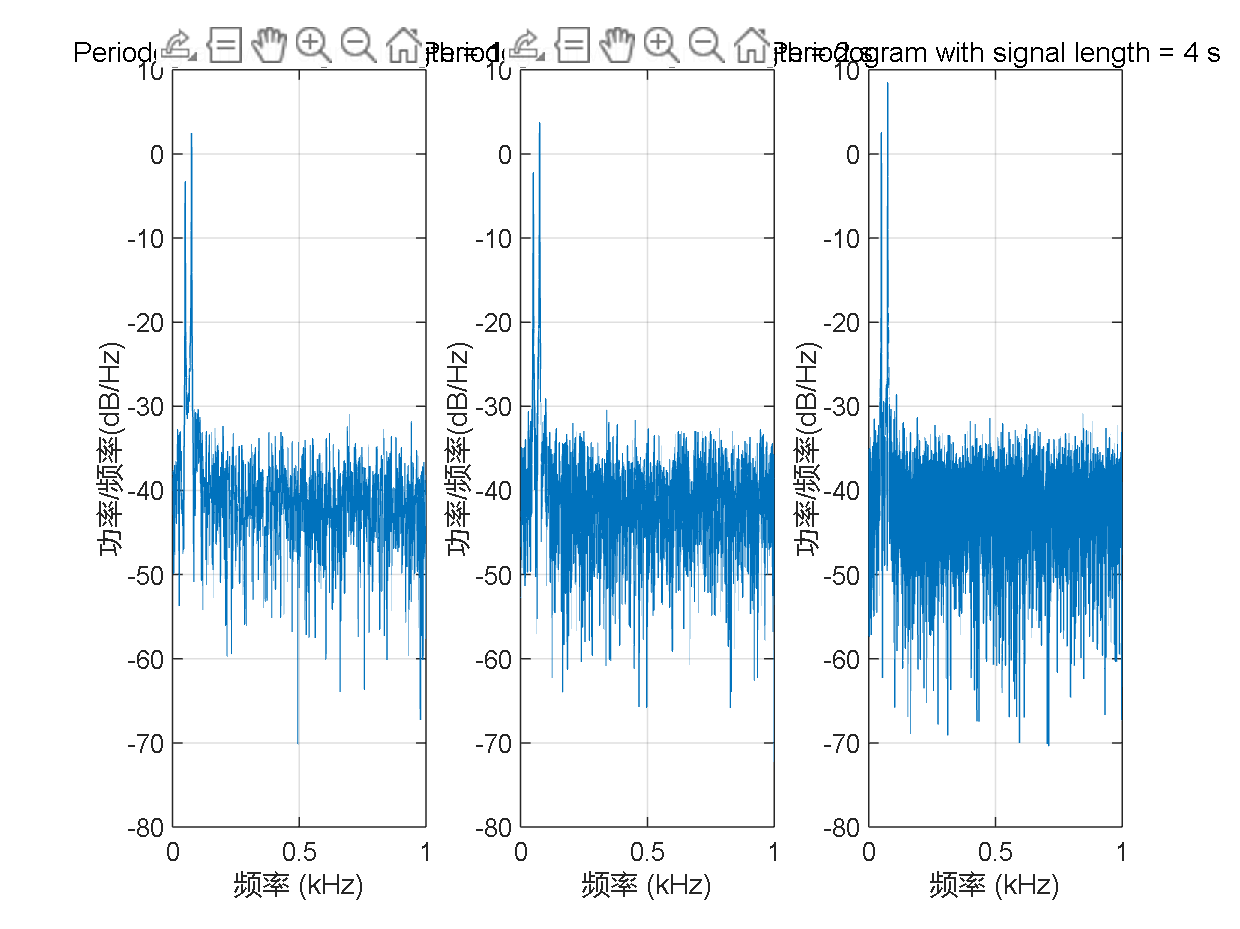

length_values = [1, 2, 4]; % Different signal lengths in seconds

figure;
for i = 1:length(length_values)
    T = length_values(i);
    t = 0:1/fs:T-1/fs;
    N = sqrt(sigma2) * randn(size(t));
    X = sin(omega1 * t) + 2 * cos(omega2 * t) + N;
    
    subplot(1, length(length_values), i);
    periodogram(X, rectwin(length(X)), [], fs);
    title(['Periodogram with signal length = ', num2str(T), ' s']);
end

(c) Effect of σ2\sigma^2σ2

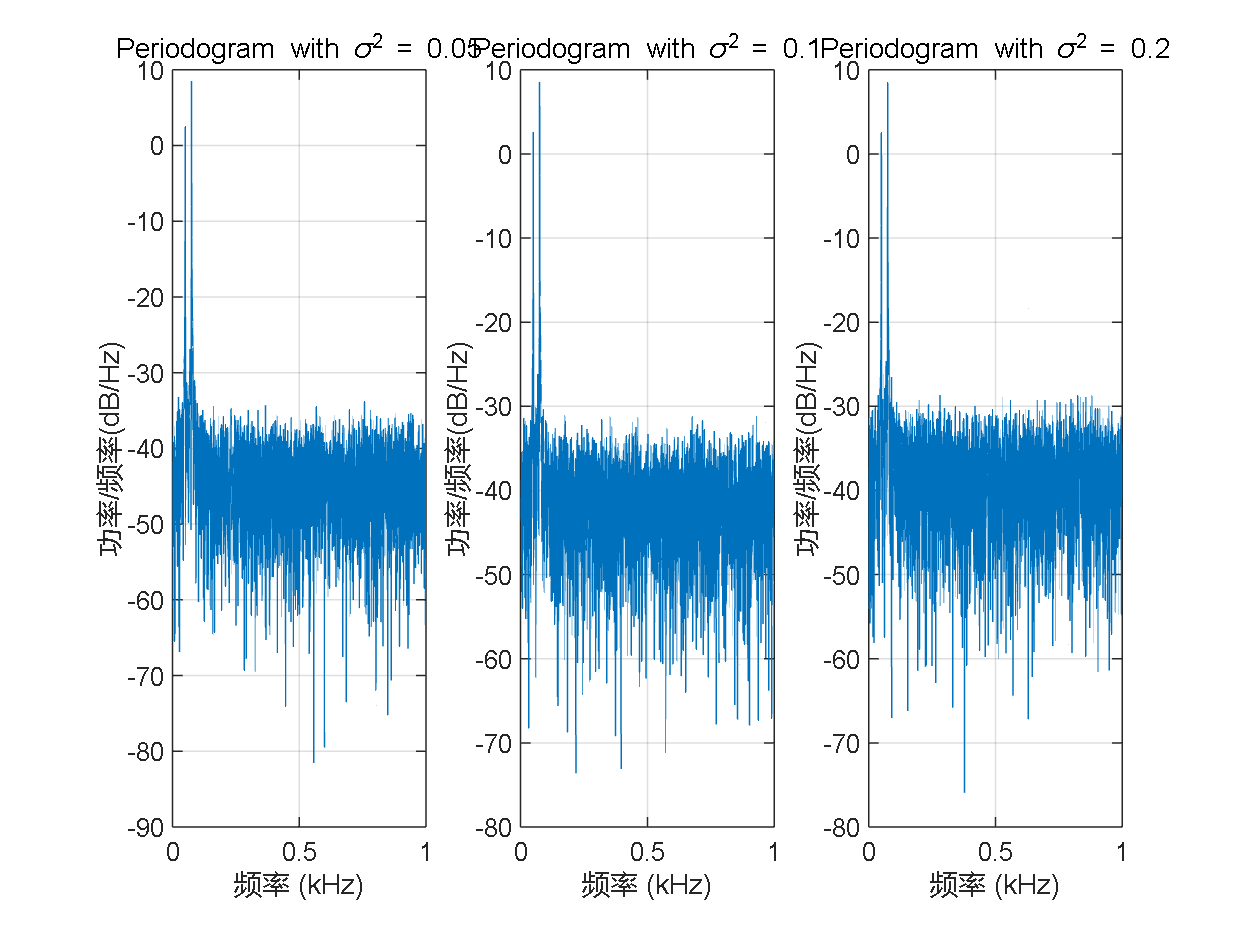

sigma2_values = [0.05, 0.1, 0.2]; % Different noise variances

figure;
for i = 1:length(sigma2_values)
    sigma2 = sigma2_values(i);
    N = sqrt(sigma2) * randn(size(t));
    X = sin(omega1 * t) + 2 * cos(omega2 * t) + N;
    
    subplot(1, length(sigma2_values), i);
    periodogram(X, rectwin(length(X)), [], fs);
    title(['Periodogram with \sigma^2 = ', num2str(sigma2)]);
end